## **OUR DATA **tr03-0083

**Execute script read_challenge.m to create struct**

**Load all the data to workspace**

%cd C:\Users\Cinth\OneDrive\Documents\MASTER_Biomed_Engineering\Master_3_Semester\APASB\TP3
%Returns val, 13xN: 13 number of biomedical signals and N the number of samples.
clear
load tr03-0083.mat %probably unneccesary because of the mainprogram part 
load tr03-0083-arousal.mat
% The first field,data.sleep_stage, is in turn another structure with 6 logical arrays
% (undefined, nonrem3, nonrem2, nonrem1, rem and wake)

% The seocnd fiels is not relevant for us.

The fields of the struct variable data are: 

 • **data.header.text**: character matrix with the information of the header file

 • **data.fs**: scalar variable with the sample frequency (200 Hz) 

 • **data.n_samples:** scalar variable with the number of samples of the PSG record • data.subject: char string with the id of the subject

 • **data.signals**: matrix with size 13xn_samples with the samples of the acquired signals

 • **data.signal_names**: cell array with 13 cells in which each cell has a string of characters with the name of the acquired biomedical signals

 • **data.sleepstages**: matrix of logical elements with size 6xn_samples in which each element indicates if a sample belongs to one of the sleep stages (undefined, nonrem3, nonrem2, nonrem1, rem and wake).

 •** data.sleepstages_names**: cell array with 6 cells in which each cell has a string of characters with the name of the corresponding sleep stage in data.sleepstages

 •** data.arousals:** matrix of logical elements with size n_arousalsxn_samples in which each element indicates if a sample belongs to one of the arousal types.

 •** data.arousals_names:** cell array with in which each cell has a string of characters with the name of the corresponding arousal type in data.arousals.

 • **data.sleepstages_annotations: **struct with different fields with the original information of the sleep stage annotations performed by the medical staff

 • **data.arousals_annotations:** struct with different fields with the original information of the arousal annotations performed by the medical staff

 •** data.target_challenge18_arousals:** array with size 1xn_samples with the information (+1, 0 or -1) used to score the non-apneic arousal detection algorithms of the Challenge 18.

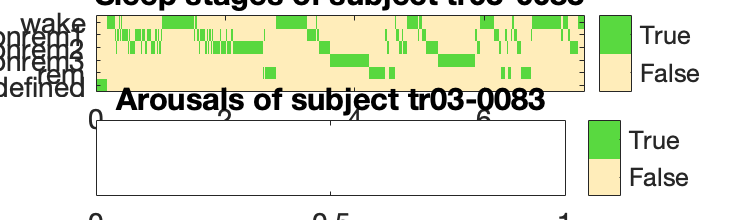

subject='tr03-0083';

if exist([subject 'data.mat'])
    load([subject 'data']) 
else
    data=read_challenge2018(subject);
end
vis_challenge2018(data);

fs=data.fs;
N=data.n_samples; %Signal length in samples
t=(0:N-1)/fs; %time

signal_names=data.signal_names;
signals=data.signals;

## 1. Preprocessing

To know which filters to use a first spectral analysis is performed. For this the function perdiodogram() is used.

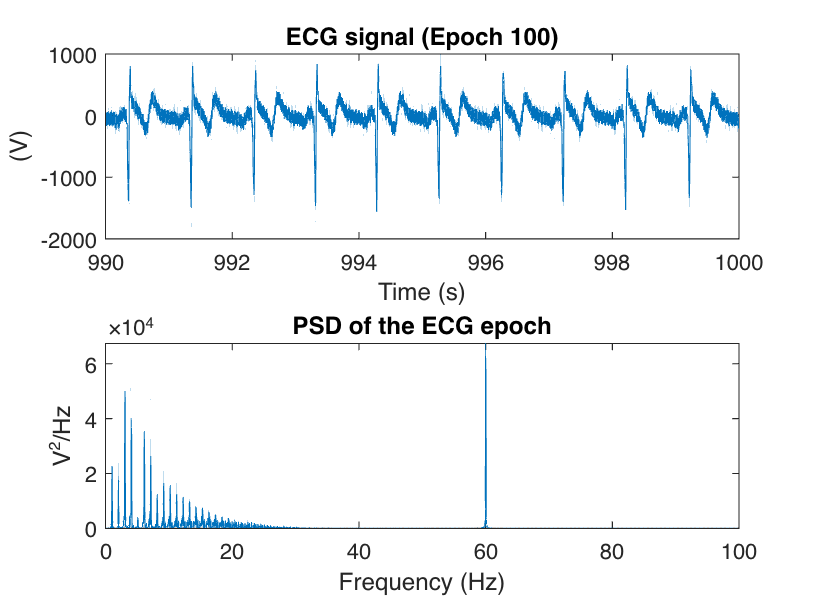

% select the window size and step size we want to use to
% compute features
epoch_time = 10; % In seconds, size of epochs
window_size = epoch_time * fs; %IN samples, size of epochs
window_step = epoch_time * fs;

n_epoch=100;

index=1:window_size;
index=index+window_step*(n_epoch-1);

ecg_ind=find(contains(signal_names,'ECG')); %Get The ECG (Reuse this for EEG etc.)
ecg_epoch=signals(ecg_ind,index); %divides ecg already into portion
figure(),clf
subplot 211
plot((index-1)/fs,ecg_epoch)
xlabel('Time (s)')
ylabel('(V)')
title(['ECG signal (Epoch ' num2str(n_epoch) ')'])
L=length(ecg_epoch);
NFFT=2^max(12,nextpow2(L));
[Pxx,f]=periodogram(detrend(ecg_epoch),rectwin(L),NFFT,fs,'onesided'); %Power per frequency

subplot 212
plot(f,Pxx)
xlabel('Frequency (Hz)')
ylabel('V^2/Hz')
title('PSD of the ECG epoch')

I see 

- High frequency noise around 60 Hz -> Bandpass filtering starting in the band 58-62 Hz

- Low pass filter staring at 40 Hz as informational frequencies are already near 0 around 30 HZ

%Load the whole signal from signals
% 1:40 -> 1*60*60s + 40*60s = 6000s, 6000*fs <- Start point (samples)
% (samples)
n_epoch_start = 6000*fs

n_epoch_start = 1200000

% 2:40 -> 6000s + 3600s = 9600s, 9600*fs <- End point (samples)
% (samples)
n_epoch_end = 9600*fs;
ecg = signals(ecg_ind,n_epoch_start:n_epoch_end);
N = length(ecg);
%Bandpass for 60Hz noise
[b,a]=butter(2,[58 62]./(fs/2),'stop');
ecgf_epoch=filtfilt(b,a,ecg_epoch);     %for portion
ecgf = filtfilt(b,a,ecg);               %for whole signal
%filter
[b,a]=butter(2,40/(fs/2),'low');
ecgf_epoch=filtfilt(b,a,ecgf_epoch);    %for portion
ecgf = filtfilt(b,a,ecgf);              %for whole signal

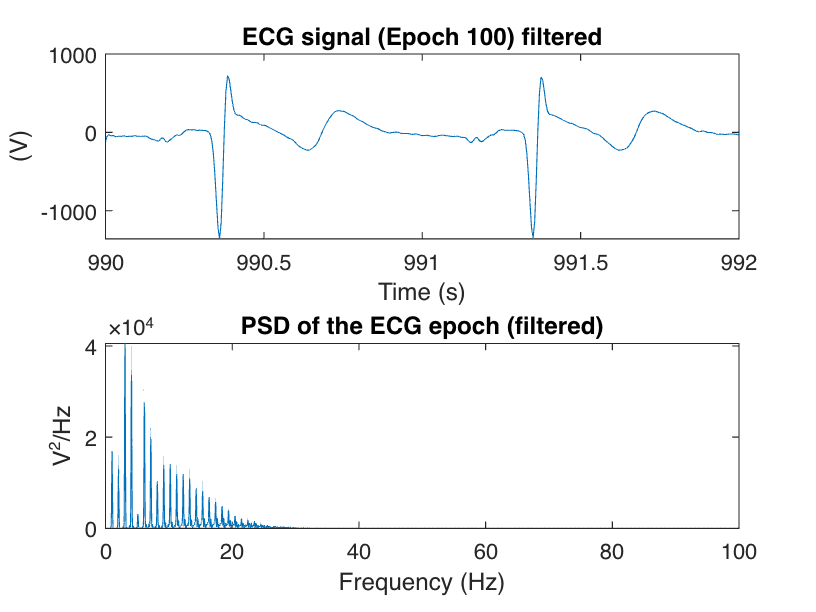

%visualizaion
figure(),clf
subplot 211
plot((index-1)/fs,ecgf_epoch)
xlabel('Time (s)')
ylabel('(V)')
xlim([990 992])
title(['ECG signal (Epoch ' num2str(n_epoch) ') filtered'])

[Pxx,f]=periodogram(detrend(ecgf_epoch),hamming(L),NFFT,fs,'onesided'); %Power per frequency

subplot 212
plot(f,Pxx)
xlabel('Frequency (Hz)')
ylabel('V^2/Hz')
title('PSD of the ECG epoch (filtered)')

## SAME PARTS AS LAB4! (it says lab3 in the script but that's wrong)

## 2. Cardiac frequency estimation in frequency domain

To determine cardiac frequency in frequency domain, we can use the power spectrum peaks. The fundamental frequency of the filtered ecg signal is the cardiac frequency. To avoid aliasing the signal is filtered again with a 4Hz low pass filter. Following, the signal will be decimated, which is practically the reduction of the sample rate of a signal, which can significantly reduce in computational complexity. But main reason for doing this is the improvement of the resolution of the signal processing. By reducing the sample rate of a signal, the effective frequency resolution is increased, which can make it easier to resolve closely spaced frequency components.

The procedure to obtain the results was the following:

-     Filter again a low pass for very low frequencies to only obtain fundamental frequency without many interference

-     Decimate the signal

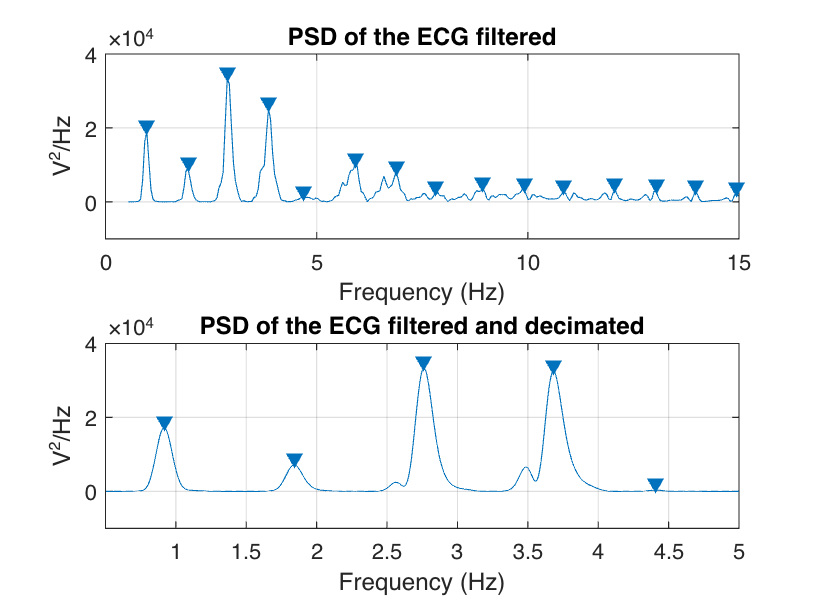

%Additional filter for the very low frequencies
%Low pass for 4Hz to get just the harmonics of the fundamental frequency
Num = [0.00212152571000884	0.0153303036381081	0.0541771171491250	0.122177637237282	0.193703349764460	0.224980133002032   0.193703349764460	0.122177637237282	0.0541771171491250	0.0153303036381081	0.00212152571000884];
r = 20;
%New sampling Frequency
fs_d = 10;
%Low pass for 4Hz frequency noise interference
ecgf = filtfilt(Num,1,ecgf);

%Decimation 
ecgf_d = decimate(ecgf,r);
N_d=length(ecgf_d);
L_d=100;

[Pxx,f]=periodogram(detrend(ecgf(1:2000)),hamming(L),NFFT,fs,'onesided'); 
%Power per frequency, 2000 = 10s * 200Hz
[Pxx_d,f_d]=periodogram(detrend(ecgf_d(101:200)),hamming(L_d),NFFT,fs_d,'onesided'); 
%Power per frequency, 100 = 10s * 10Hz

figure()
subplot 211
%plot(f,Pxx)
% HOW TO APPLY A THRESHOLD for the PEAKS???
findpeaks(Pxx(f<15 & f>0.5),f(f<15 & f>0.5),'MinPeakDistance',0.7,'MinPeakProminence',0.2);
xlabel('Frequency (Hz)')
xlim([0 15])
ylabel('V^2/Hz')
title('PSD of the ECG filtered')
subplot 212
%plot(f_d,Pxx_d)
findpeaks(Pxx_d(f_d<10 & f_d>0.5),f_d(f_d<10 & f_d>0.5),'MinPeakDistance',0.7,'MinPeakProminence',0.2);
xlabel('Frequency (Hz)')
ylabel('V^2/Hz')
title('PSD of the ECG filtered and decimated')

Both the PSD of the decimated and undecimated signal look very clean. The last peak detected in the PSD of the undecimated signal makes no sense, as there is not really a peak to be identified.

As the signal can be considered stationary, the periodogram function might perform just as good as the burg algorithm for the PSD calculation. The Burg method adapts to changes in the signal and is therefore suitable for stationary and non-stationary signals. Whereas the periodogram only performs well for stationary signals.

The periodogram method is relatively simple to implement and computationally less demanding than the Burg method. Burg method might have higher resolution and better noise reduction, but as our signal is stationary and filtered using a Hamming window as weighting function, the resolution of the periodogram estimate is increased.

The next section does the following:

-     Cut signal into sections of 10s

-     Do PSD for each segment

-     Count cardiac beats in each interval using PSD peaks

-     Save PSD and cardiac BPM in a matrix respectively for each 10s

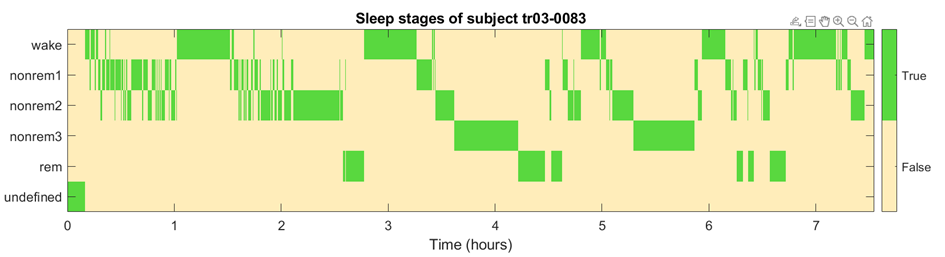

%index window size for dec signal 
window_size = epoch_time * fs_d; %IN samples, size of epochs
window_step = epoch_time * fs_d;
t_d=(0:N_d-1)/fs_d; %time
Pxx_M_d=zeros(2049,1);
fcard_latmin_d=zeros();
% counts to see which condition was TRUE for the fcard_latmin calculation
count_1 = 0;
count_2 = 0;

for n_epoch = 1:N_d/fs_d/epoch_time
    ecgfd_epoch = ecgf_d(t_d>=(n_epoch-1)*epoch_time & t_d<=n_epoch*epoch_time);
    t_epoch_d = t_d(t_d>=(n_epoch-1)*epoch_time & t_d<=n_epoch*epoch_time);
    % Calculate PSD parameters
    L_d = length(ecgfd_epoch);
    NFFT_d=2^max(12,nextpow2(L_d)); 

    [Pxx_d,f_d]=periodogram(detrend(ecgfd_epoch),hamming(L_d),NFFT_d,fs_d,'onesided'); %Power per frequency
    Pxx_M_d(:,n_epoch)=Pxx_d;

    [peaks_d,fpeaks_d]=findpeaks(Pxx_d(f_d<10 & f_d>0.5),f_d(f_d<10 & f_d>0.5),'MinPeakDistance',0.6,'MinPeakProminence',1000);
    fpeaks_d = fpeaks_d(fpeaks_d<=4);
    candidates = diff(fpeaks_d);
    
    if min(candidates) ~= max(candidates)
       edges = min(candidates):range(candidates)/100:max(candidates);
       %How many different values are in the range of edges
       bin = discretize(candidates,edges); 
       %calculate estimated cardiac frequency
       fcard_d = mean([edges(mode(bin)) edges(mode(bin)+1)]);
       %save into cardiac freq beats per minute vector
       count_1 = count_1 + 1;
    else
       fcard_d = mean(candidates);
       count_2 = count_2 + 1;
    end
    fcard_latmin_d(:,n_epoch)=60*fcard_d;
end
count_1;
count_2;

The calculation of the fcard is mainly done using the first condition, which is more robust than the second one.

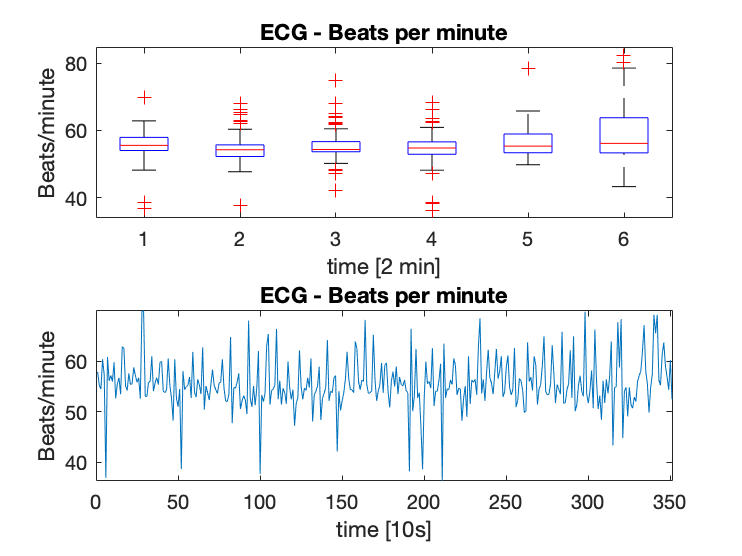

BPM=zeros(1,60);
% 2716 * 1 = 2716 * ein 10 sekunden abschnitt 
% 10 sekunden * 6 = 1 Minute 
% floor(2716/60) =
for j=1:6
    if j == 1
        BPM(j,:)=fcard_latmin_d(j:j*60);
    else 
        BPM(j,:)=fcard_latmin_d((j-1)*60:j*60-1);
    end
end
BPM=BPM';
figure()
subplot 211
boxplot(BPM)
title('ECG - Beats per minute')
ylabel('Beats/minute')
xlabel('time [2 min]')
subplot 212
% exclude outliers
fcard_latmin_df = fcard_latmin_d(fcard_latmin_d>=35 & fcard_latmin_d<= 70);
plot(1:length(fcard_latmin_df),fcard_latmin_df)
title('ECG - Beats per minute')
ylabel('Beats/minute')
xlabel('time [10s]')
xlim([0 length(fcard_latmin_df)])

The results show a big variability within the first hour. When comparing this to the annotations of the sleepstages, this makes sense, as within the first 10 minutes the subject sleep stage changed from REM to wake stage. 

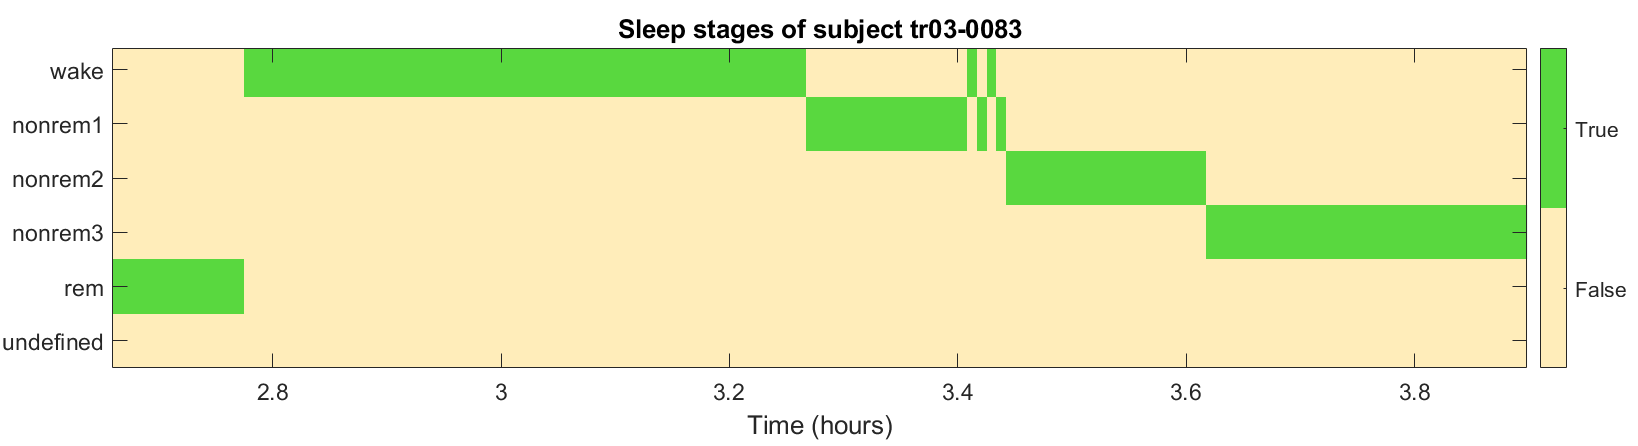

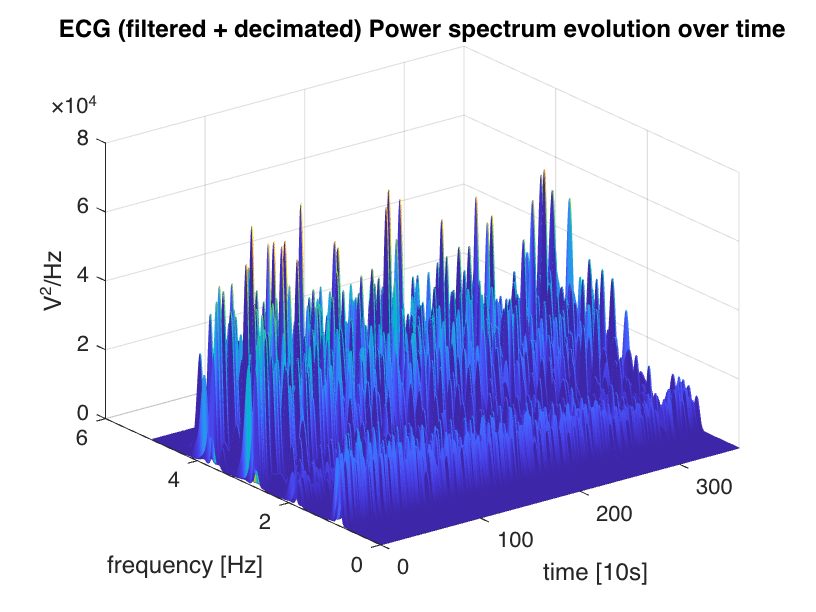

figure()
mesh(1:360,f_d(f_d<20),Pxx_M_d(f_d<20,:))
xlabel('time [10s]')
ylabel('frequency [Hz]')
zlabel('V^2/Hz')
xlim([0 360])
title('ECG (filtered + decimated) Power spectrum evolution over time')

## 3. Heart rate variability (HRV) spectral analysis

Heart rate variability (HRV) is a non-invasive method to evaluate the regulation of the ANS. To analyse it we use the Pan-Tompkins method, which is an algorithm used in the field of biomedical signal processing to detect the presence of QRS complexes, which are the characteristic features of the cardiac electrical activity in an electrocardiogram (ECG) signal. The algorithm is based on the computation of several signal features, such as the slope, width, and amplitude of the QRS complex, which are then used to determine whether a QRS complex is present or not.

### 3.1 Preprocessing

From the marks of a QRS complex detector obtain a vector of marks for each R point detected in each single 30 second epoch, we can calculate the heart rate and then observe its changes. 

For this task the 4Hz filter and the decimation are not used.

%Bandpass for 60Hz noise
[b,a]=butter(2,[58 62]./(fs/2),'stop');
ecgf_epoch=filtfilt(b,a,ecg_epoch);     %for portion
ecgf = filtfilt(b,a,ecg);               %for whole signal
%filter
[b,a]=butter(2,40/(fs/2),'low');
ecgf_epoch=filtfilt(b,a,ecgf_epoch);    %for portion
ecgf = filtfilt(b,a,ecgf);              %for whole signal

Num = [0.00212152571000884	0.0153303036381081	0.0541771171491250	0.122177637237282	0.193703349764460	0.224980133002032   0.193703349764460	0.122177637237282	0.0541771171491250	0.0153303036381081	0.00212152571000884];
r = 20;
%New sampling Frequency
fs_d = 10;
%Low pass for 4Hz frequency noise interference
ecgf = filtfilt(Num,1,ecgf);

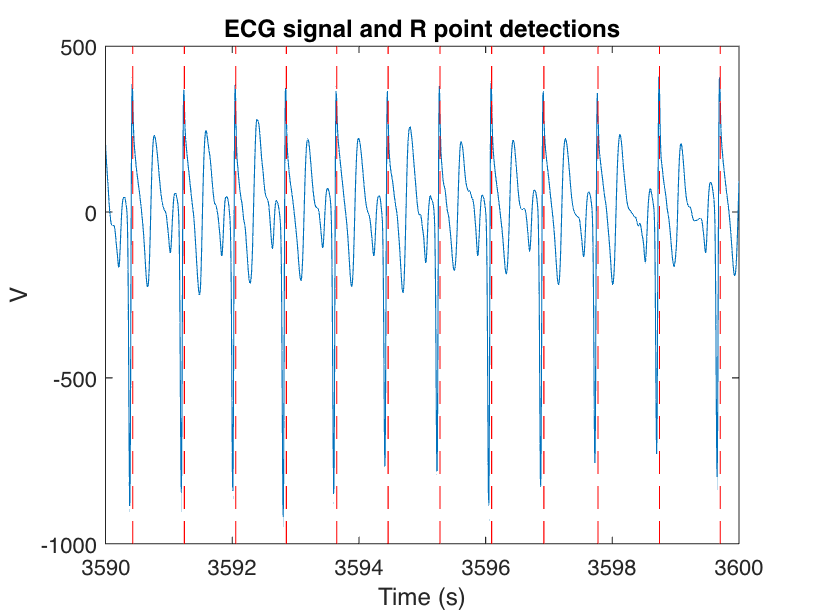

ecgf_epoch = ecgf(t>=(n_epoch-1)*epoch_time & t<=n_epoch*epoch_time);
t_epoch = t(t>=(n_epoch-1)*epoch_time & t<=n_epoch*epoch_time);

[Ramp,Rindex]=pan_tompkin(ecgf_epoch,fs,0);

figure()
plot(t_epoch,ecgf_epoch)
hold on
plot(t_epoch([Rindex;Rindex]),ylim'*ones(1,length(Rindex)),'--r')
xlabel('Time (s)')
ylabel('V')
title('ECG signal and R point detections')
hold off

From these R marks, the RR series can be obtained by differentiating between R points.

The time associated with each RR value corresponds to the position of the R-point of the second beat when the difference is made:

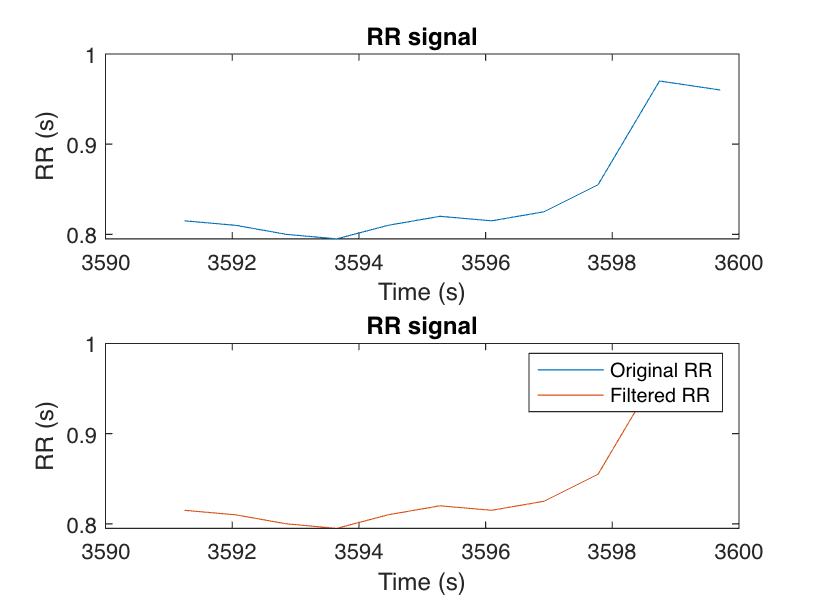

RR=diff(Rindex)/fs;
tRR=t_epoch(Rindex(2:end));
figure()
subplot(2,1,1)
plot(tRR,RR)
xlabel('Time (s)')
ylabel('RR (s)')
title('RR signal')
[RRf,tRRf,RRout,tRRout]=filterRR(RR,tRR,1,0.2);
subplot(2,1,2)
plot(tRR,RR,tRRf,RRf)
xlabel('Time (s)')
ylabel('RR (s)')
title('RR signal')
legend('Original RR','Filtered RR')

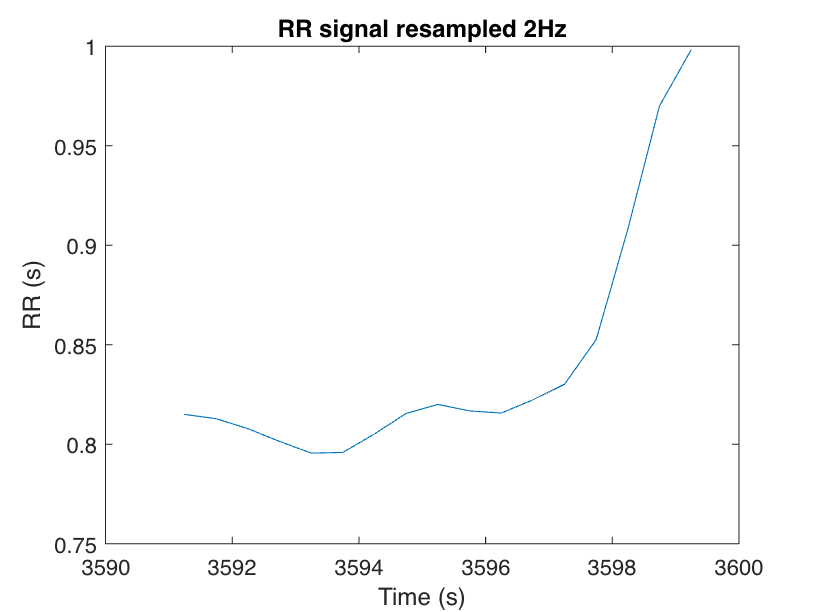

fsRR=2;
t2Hz=tRRf(1):1/fsRR:tRRf(end);
RR2Hz=spline(tRRf,RRf,t2Hz);
figure()
plot(t2Hz,RR2Hz)
xlabel('Time (s)')
ylabel('RR (s)')
title('RR signal resampled 2Hz')

To correct possible artefacts in the RR signal and failures in the detector, it is recommended to apply a filter to the RR signal (filterRR.m):

Finally, to perform the frequency analysis of the RR signal we need to have the signal sampled at a constant frequency. Resampling a signal at a constant frequency allows to better analyze the signal. A signal resampled at a low frequency can be used for low-frequency signal analysis.

For this, Spline Interpolation is used, which is a method of constructing a smooth curve that passes through a given set of data points. The idea behind spline interpolation is to approximate a smooth function that is well-behaved and easy to evaluate while closely matching the input data. 

Since VLF (0.003 - 0.04), LF (0.04  0.15), HF (0.15 - 0.4) frequency bands of the RR signal are very low values, we can resample the RR signal at 2 Hz instead of 200Hz. 

Perform all these steps for the whole signal 

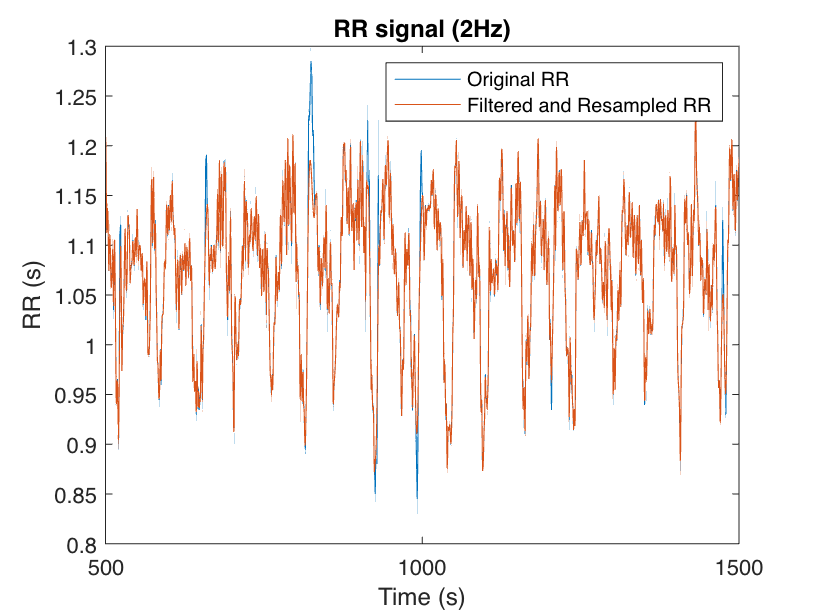

% All operations
t=(0:N-1)/fs; %time
%% Pan tompkins QRS detection
[~,Rindex] = pan_tompkin(ecgf,fs,0);
%% RR Interval calculation
RR = diff(Rindex)/fs;
tRR = t(Rindex(2:end));
%% Filter 
[RRf,tRRf,RRout,tRRout]=filterRR(RR,tRR,1,0.2);
%% Resampling at 2 Hz 
fsRR=2;
t2Hz =tRRf(1):1/fsRR:tRRf(end);
RR2Hz =spline(tRRf,RRf,t2Hz);
%% Plot of RR and RR2Hz
figure()
plot(tRR,RR)
hold on
plot(t2Hz,RR2Hz)
xlabel('Time (s)')
ylabel('RR (s)')
xlim([500 1500])
title('RR signal (2Hz)')
legend('Original RR','Filtered and Resampled RR')
hold off

This signal is now ready for HRV analysis. Each value in the RR2Hz values represents the duration of the RR interval. 

In Second 722 a periodic RR Interval occurs. Which translates to 12 minutes after the start of our section (minute 160) and ends around 1225s, i.e., 20 minutes after the start of the considered section. In the time from minute 172 to 180, in hours from 2.87 to 3 hours. Here no arousals of the subject were annotated.

### 3.2 Analysis

For the analysis of the HRV time-frequency spectrogram or scalogram could be used. Scalograms can be more effective than spectrograms for detecting non-stationary and transient components of signals and for identifying patterns that change over time. This is why the scalogram is chosen for this analysis.

A scalogram is a graphical representation of the scale-dependent power spectrum of a signal, which shows how the power (or energy) of the signal is distributed across different frequency scales. It can be thought of as a time-frequency plot, where the x-axis represents time and the y-axis represents scale.

In the context of a scalogram, scale refers to the size of the wavelets used to decompose the signal. The scale of a wavelet determines its frequency band, with larger scales corresponding to lower frequencies and smaller scales corresponding to higher frequencies.

% INPUTS
% RR2Hz % was calculated for 60 seconds each
N_RR = length(RR2Hz);
t2Hz; % time of the RR values
RR2Hz; % RR values after processing 
epoch_time=30; % time sections analyzed
Pxx_M_RR = zeros(2049,1);
for n_epoch = 1:N_RR/fsRR/epoch_time
    RR2Hz_epoch = RR2Hz(t2Hz>=(n_epoch-1)*epoch_time & t2Hz<=n_epoch*epoch_time);
    t_epoch_RR = t2Hz(t2Hz>=(n_epoch-1)*epoch_time & t2Hz<=n_epoch*epoch_time);
    % Calculate PSD parameters
    L_RR = length(RR2Hz_epoch);
    NFFT_RR =2^max(12,nextpow2(L_d)); 

    [Pxx_RR,f_RR]=periodogram(detrend(RR2Hz_epoch),hamming(L_RR),NFFT_RR,fsRR,'onesided'); %Power per frequency
    Pxx_M_RR(:,n_epoch)=Pxx_RR;
end

% RR2Hz in 30 second sections
% 
VLF = [0.003  0.04];
LF = [0.04  0.15];
HF = [0.15  0.4];

Pband_VLF_V = zeros();
Pband_LF_V = zeros();
Pband_HF_V = zeros();
loop_end = size(Pxx_M_RR);
loop_end = loop_end(2);
for n_epoch = 1:loop_end
    ecgfd_epoch = ecgf_d(t_d>=(n_epoch-1)*epoch_time & t_d<=n_epoch*epoch_time);
    t_epoch_d = t_d(t_d>=(n_epoch-1)*epoch_time & t_d<=n_epoch*epoch_time);
    %  function [Pmband,Pmband2Pm,Pm]=powerband(Pxx,f,fband)
    [Pband_VLF,Pband2P_VLF,P_VLF]=powerband(Pxx_M_RR(:,n_epoch),f,VLF,0);
    [Pband_LF,Pband2P_LF,P_LF]=powerband(Pxx_M_RR(:,n_epoch),f,LF,0);
    [Pband_HF,Pband2P_HF,P_HF]=powerband(Pxx_M_RR(:,n_epoch),f,HF,0);

    Pband_VLF_V(n_epoch) = Pband_VLF;
    Pband_LF_V(n_epoch) = Pband_LF;
    Pband_HF_V(n_epoch) = Pband_HF;
end
count_1;
count_2;

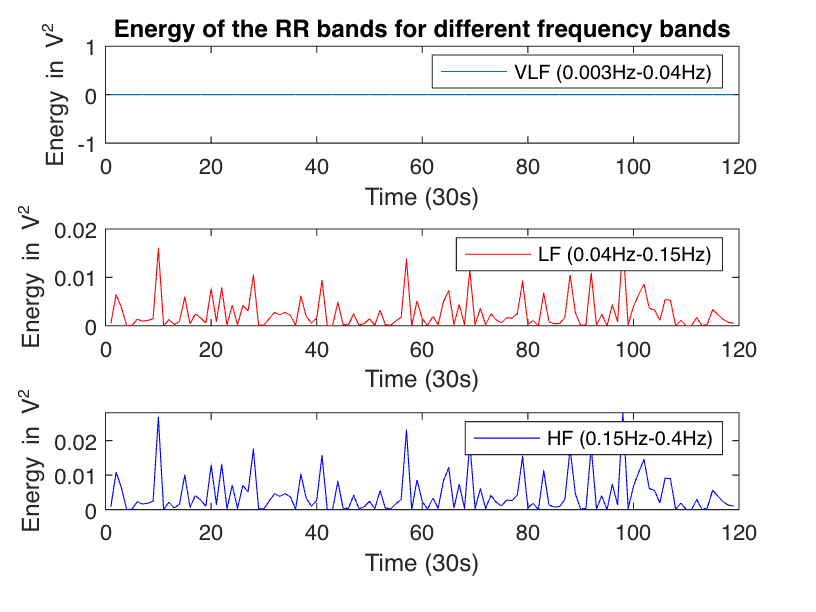

figure
subplot 311
plot(1:loop_end, Pband_VLF_V)
title('Energy of the RR bands for different frequency bands')
xlabel('Time (30s)')
ylabel('Energy in V^2')
legend('VLF (0.003Hz-0.04Hz)')
subplot 312
plot(1:loop_end, Pband_LF_V,'r')
xlabel('Time (30s)')
ylabel('Energy in V^2')
legend('LF (0.04Hz-0.15Hz)')
subplot 313
plot(1:loop_end, Pband_HF_V,'b')
xlabel('Time (30s)')
ylabel('Energy in V^2')
legend('HF (0.15Hz-0.4Hz)')

## Respiratory frequency estimation in frequency domain

abd_ind=find(contains(signal_names,'ABD')); %Get The ECG (Reuse this for EEG etc.)
t_abd = (n_epoch_start:n_epoch_end)/fs;
abd = signals(abd_ind,n_epoch_start:n_epoch_end);
N = length(abd);

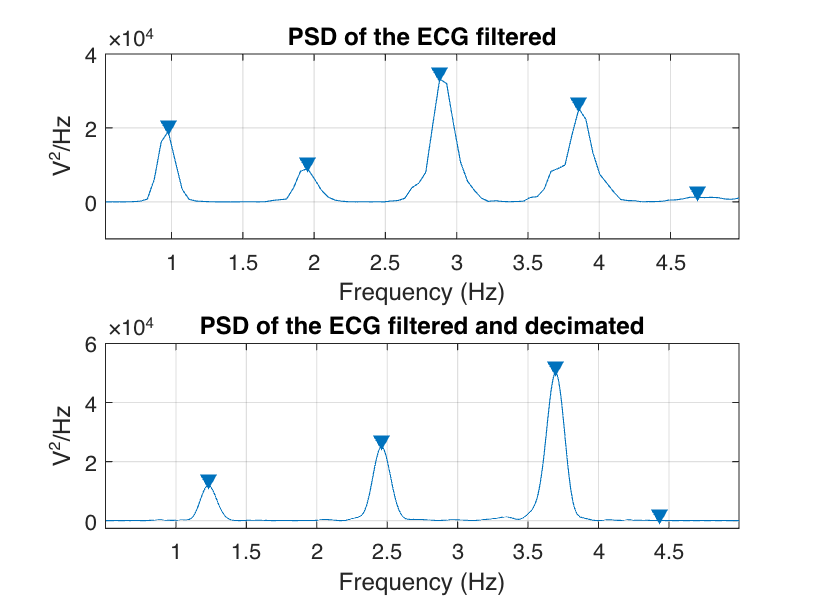

[Pxx,f]=periodogram(detrend(ecgf(1:2000)),hamming(L),NFFT,fs,'onesided'); 
%Power per frequency, 2000 = 10s * 200Hz


clf,figure()
subplot 211
%plot(f,Pxx)
findpeaks(Pxx(f<5 & f>0.5),f(f<5 & f>0.5),'MinPeakDistance',0.7,'MinPeakProminence',0.2);
xlabel('Frequency (Hz)')
ylabel('V^2/Hz')
title('PSD of the ECG filtered')
subplot 212
%plot(f_d,Pxx_d)
findpeaks(Pxx_d(f_d<5 & f_d>0.5),f_d(f_d<5 & f_d>0.5),'MinPeakDistance',0.7,'MinPeakProminence',0.2);

xlabel('Frequency (Hz)')
ylabel('V^2/Hz')
title('PSD of the ECG filtered and decimated')

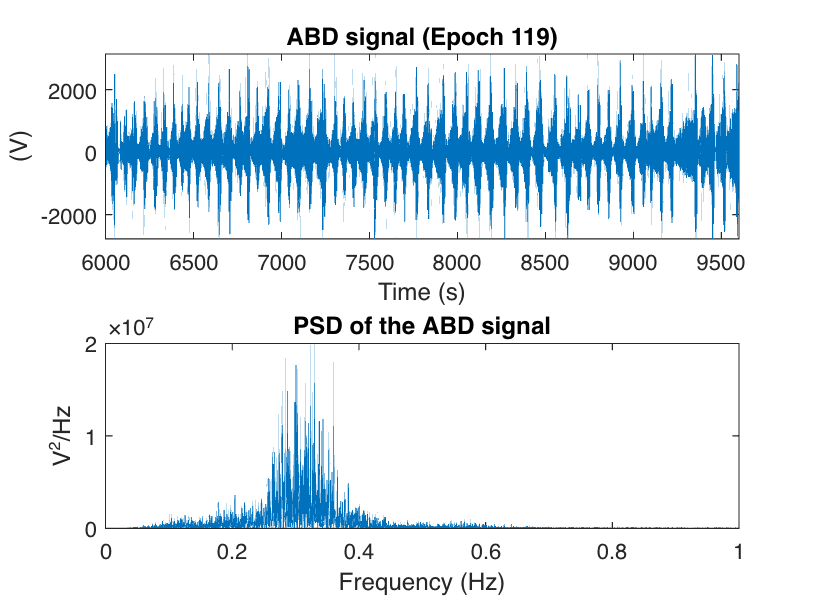


clf,figure()
subplot 211
plot(t_abd,abd)
xlabel('Time (s)')
ylabel('(V)')
title(['ABD signal (Epoch ' num2str(n_epoch) ')'])
xlim([6000 9600])

L=length(abd);
NFFT=2^max(12,nextpow2(L));
[Pxx,f]=periodogram(detrend(abd),rectwin(L),NFFT,fs,'onesided'); %Power per frequency


subplot 212
plot(f,Pxx)
xlabel('Frequency (Hz)')
ylabel('V^2/Hz')
xlim([0 1])
%ylim([0 2e3])
title('PSD of the ABD signal')

Aparently no filter is necessary in the ABDOMINAL record, as all the frequencies are inside the physiological level.

Pxx_M=zeros(2049,1);
fresp_latmin=zeros();
fs=200;
epoch_time=10;

for n_epoch = 1:N/fs/epoch_time %360 epochs
    abd_epoch = abd(t_abd>=((n_epoch-1)*epoch_time+t_abd(1)) & t_abd<=(n_epoch*epoch_time)+t_abd(1));
    %t_epoch = t_abd(t_abd>=(n_epoch-1)*epoch_time & t_abd<=n_epoch*epoch_time);
    % Calculate PSD parameters
    L = length(abd_epoch);
    NFFT=2^max(12,nextpow2(L)); 

    [Pxx,f]=periodogram(detrend(abd_epoch),hamming(L),NFFT,fs,'onesided'); %Power per frequency
    Pxx_M(:,n_epoch)=Pxx;

    [peaks,fpeaks]=findpeaks(Pxx(f<10 & f>0),f(f<10 & f>0),'MinPeakDistance',0.05);
    %fpeaks = fpeaks(fpeaks<=4);
    candidates = diff(fpeaks);
    edges = min(candidates):range(candidates)/100:max(candidates);
    
    %If there is only one candidate discretize gives an error
    if isempty(candidates)==1 %length==0
        fresp = nan;
 
    elseif length(candidates)==1
        fresp = candidates;
    else
        %How many values are in the range of edges
        bin = discretize(candidates,edges); 
        %calculate estimated cardiac frequency
        fresp = mean([edges(mode(bin)) edges(mode(bin)+1)]);
    end
    
    
    

    fresp_latmin(:,n_epoch)=60*fresp;
end



The calculation of the fcard is mainly done using the first condition, which is more robust than the second one.

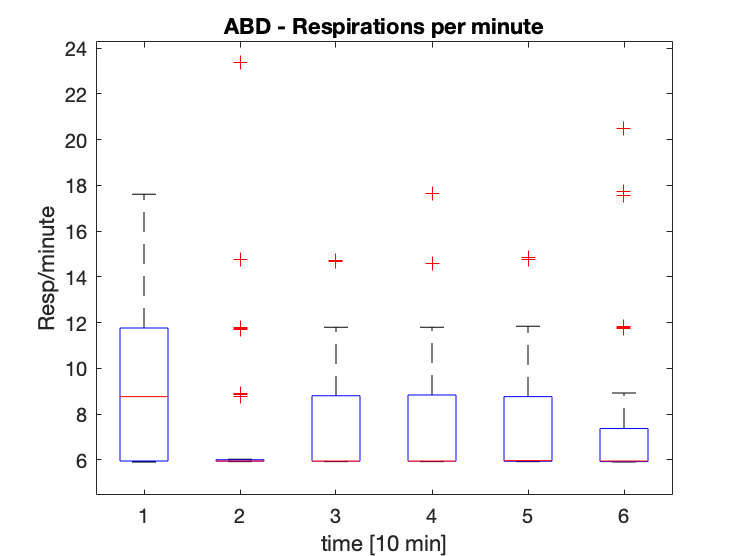

RPM=zeros(1,60);
% 2716 * 1 = 2716 * ein 10 sekunden abschnitt 
% 10 sekunden * 6 = 1 Minute 
% floor(2716/60) =
for j=1:6
    if j == 1
        RPM(j,:)=fresp_latmin(j:j*60);
    else 
        RPM(j,:)=fresp_latmin((j-1)*60:j*60-1);
    end
end
RPM=RPM';


clf, figure()

boxplot(RPM)
title('ABD - Respirations per minute')
ylabel('Resp/minute')
xlabel('time [10 min]')
hold on

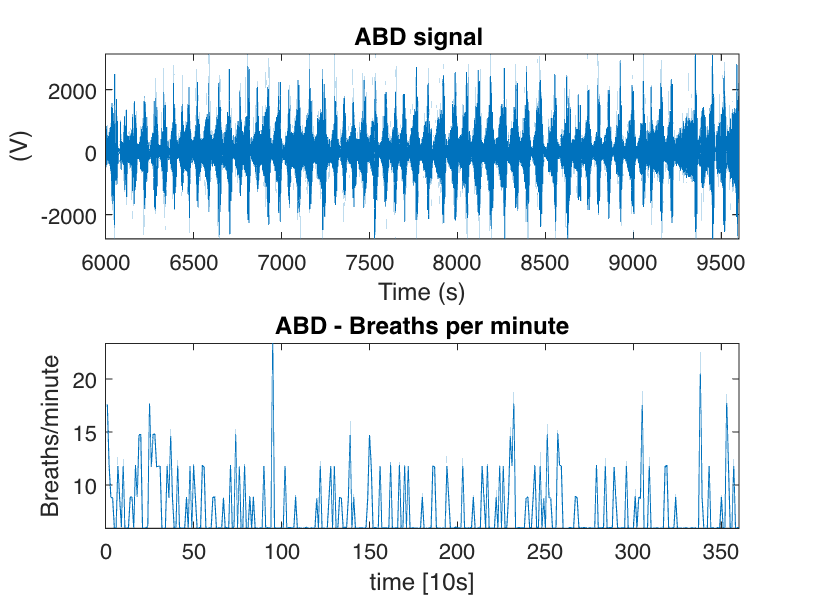



clf,figure()
subplot 211
plot(t_abd,abd)
xlabel('Time (s)')
ylabel('(V)')
title(['ABD signal '])
xlim([n_epoch_start n_epoch_end]/fs)
hold on

subplot 212
plot(1:length(fresp_latmin),fresp_latmin)
title('ABD - Breaths per minute')
ylabel('Breaths/minute')
xlabel('time [10s]')
xlim([0 360])
hold off

mean(fresp_latmin, 'omitnan')

ans = 7.6417

## EEG energy and frequency characterization during sleep

EEG is a very nonstationary signal, meaning that in general terms it can change a lot with time. Therefore the first approach to study the energy of its frequencies will be done with a time frequency representation, concretely a reassigned spectogram, in order to see how this energies change over the sleeping period.

Maybe compute the power bands of the characteristic waves?

five sub-bands: delta (δ, 0.5–4 Hz), theta (θ,4–8 Hz), alpha (α,8–12 Hz), sigma (σ,12–16 Hz) and beta (β, 16–40 Hz)

eeg_ind=find(contains(signal_names,'F3-M2')); %Get The ECG (Reuse this for EEG etc.)
t_eeg = (n_epoch_start:n_epoch_end)/fs;
eeg = signals(eeg_ind,n_epoch_start:n_epoch_end);
N = length(eeg)-1;

%Bandpass for 60Hz noise
[b,a]=butter(2,[58 62]./(fs/2),'stop');
eeg = filtfilt(b,a,eeg);               %for whole signal





order = arord(eeg, 1000, 1, 3);

%Calculate NFFT 
L = length(eeg);
%NFFT=2^max(12,nextpow2(L));
NFFT=2^12;
D=60*fs;
S=0.5*D;

% Estimate PSD using pburg
[Pxx_burg, f_b] = pburg(detrend(eeg), order, 3*NFFT,fs,'onesided');
[Pxx_w,f_w]=pwelch(detrend(eeg),D,S,NFFT,fs,'onesided'); %Power per frequency
[Pxx_h,f_h]=periodogram(detrend(eeg),hamming(L),NFFT,fs,'onesided'); %Power per frequency


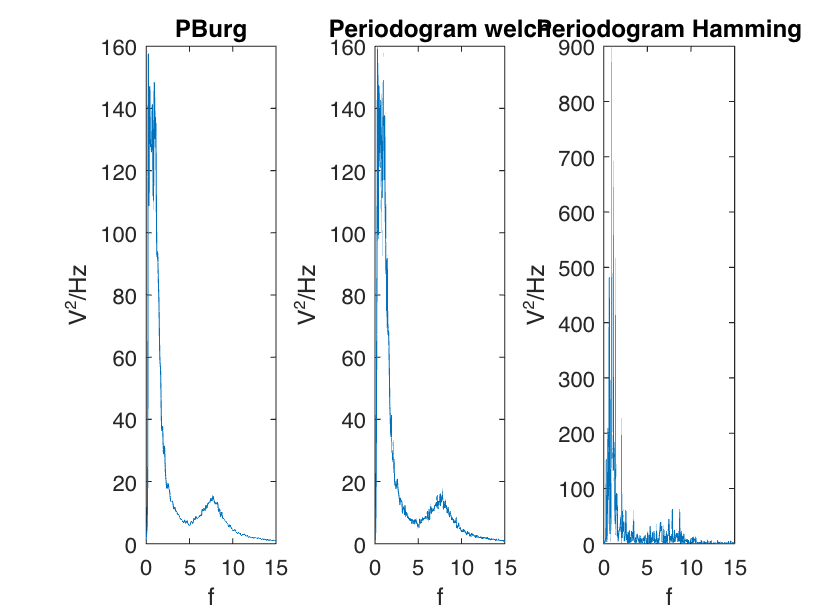

figure()
subplot 131
plot(f_b,Pxx_burg)
xlabel('f'),ylabel('V^2/Hz')
title(['PBurg'])
xlim([0 15])

subplot 132
plot(f_w,Pxx_w)
xlabel('f'),ylabel('V^2/Hz')
title(['Periodogram welch'])
xlim([0 15])

subplot 133
plot(f_h,Pxx_h)
xlabel('f'),ylabel('V^2/Hz')
title(['Periodogram Hamming'])
xlim([0 15])

Powerbands

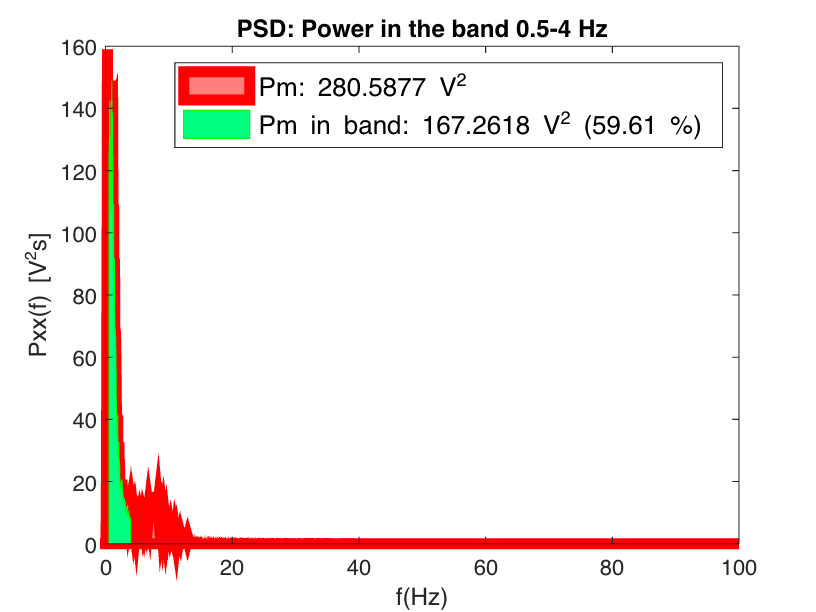

[Pmband,Pmband2Pm_delta,Pm]=powerband(Pxx_w',f_w',[0.5 4],1);

[Pmband,Pmband2Pm_teta,Pm]=powerband(Pxx_w',f_w',[4 8],0);
[Pmband,Pmband2Pm_alfa,Pm]=powerband(Pxx_w',f_w',[8 12],0);
[Pmband,Pmband2Pm_sigma,Pm]=powerband(Pxx_w',f_w',[12 16],0);

[Pmband,Pmband2Pm_beta,Pm]=powerband(Pxx_w',f_w',[16 40],0);

At this point meybe it would be interesting to see the power progression of the five frequencies of interest during the sleep (as in blocs of 10s?)

And to mean it across all the leads?



%Faria falta fe run downsampling per poder fer una representació temps
%frequencia

% % %Plot
% % figure()
% % plot(t_eeg,eeg)
% % title('EEG - Beats per minute')
% % ylabel('microVolts')
% % xlabel('time')
% % ylim([-300 300])
% % xlim([n_epoch_start n_epoch_end]/fs)
% % D=1*fs;
% % S=D-1;
% % NFFT=2^max([1 nextpow2(D)]);
% % window=hamming(D);
% % 
% % [STFT,f,tSTFT,SPEC]=spectrogram (eeg,window,S,NFFT,fs,'reassigned');
% % figure()
% % imagesc(tSTFT,f,SPEC)
% % xlabel('t[s]'),ylabel('f[Hz]')
% % title(['Spectrogram of RRsim(t) with a ' num2str(D) ' s Hamming window [V^2/Hz]'])
% % set(gca,'YDir','normal')
% % set(gca,'XLim',[t(1) t(end)])
% % YL=[0 0.5];
% % set(gca,'YLim',YL)
epoch_time=10;%s

fwafe_delta = [0.5 4];
fwafe_teta = [4 8];
fwafe_alfa = [8 12];
fwafe_sigma = [12 16];
fwafe_beta = [16 40];
Pxx_mean_d=zeros(6,360);
Pxx_mean_t=zeros(6,360);
Pxx_mean_a=zeros(6,360);
Pxx_mean_s=zeros(6,360);
Pxx_mean_b=zeros(6,360);

for element = 1:6 %the eeg signals
    signals=data.signals;
    eeg=signals(element,n_epoch_start:n_epoch_end); 

    [Pxx_rel_d,~]=relative_power_epoch(eeg,t_eeg, fwafe_delta,fs, epoch_time);
    Pxx_mean_d(element,:)=Pxx_rel_d;
    
    [Pxx_rel_t,~]=relative_power_epoch(eeg,t_eeg, fwafe_teta,fs, epoch_time);
    Pxx_mean_t(element,:)=Pxx_rel_t;
    
    [Pxx_rel_a,~]=relative_power_epoch(eeg,t_eeg, fwafe_alfa,fs, epoch_time);
    Pxx_mean_a(element,:)=Pxx_rel_a;
    
    [Pxx_rel_s,~]=relative_power_epoch(eeg,t_eeg, fwafe_sigma,fs, epoch_time);
    Pxx_mean_s(element,:)=Pxx_rel_s;
    
    [Pxx_rel_b,~]=relative_power_epoch(eeg,t_eeg, fwafe_beta,fs, epoch_time);
    Pxx_mean_b(element,:)=Pxx_rel_b;
end

Relative energy across the six eeg derivations for the hour of analysis

t_min = (1:360)/6;

fig = figure, clf

fig =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


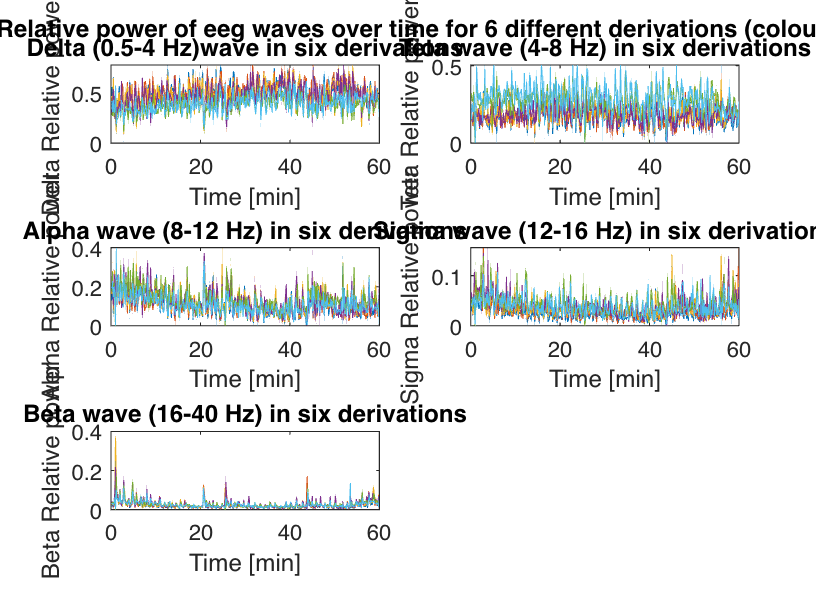

subplot 321
plot(t_min,Pxx_mean_d)
title('Delta (0.5-4 Hz)wave in six derivations')
ylabel('Delta Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 322
plot(t_min,Pxx_mean_t)
title('Teta wave (4-8 Hz) in six derivations')
ylabel('Teta Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 323
plot(t_min,Pxx_mean_a)
title('Alpha wave (8-12 Hz) in six derivations')
ylabel('Alpha Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 324
plot(t_min,Pxx_mean_s)
title('Sigma wave (12-16 Hz) in six derivations')
ylabel('Sigma Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 325
plot(t_min,Pxx_mean_b)
title('Beta wave (16-40 Hz) in six derivations')
ylabel('Beta Relative power')
xlabel ('Time [min]')
xlim([0 60])

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
mytitle='Relative power of eeg waves over time for 6 different derivations (colours)';
title(han,mytitle);

The tendency of the relative power of the different waves mostly matches in between the six deviations. Therefore we will mean across the six deviations to obtain only one

fig=figure

fig =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


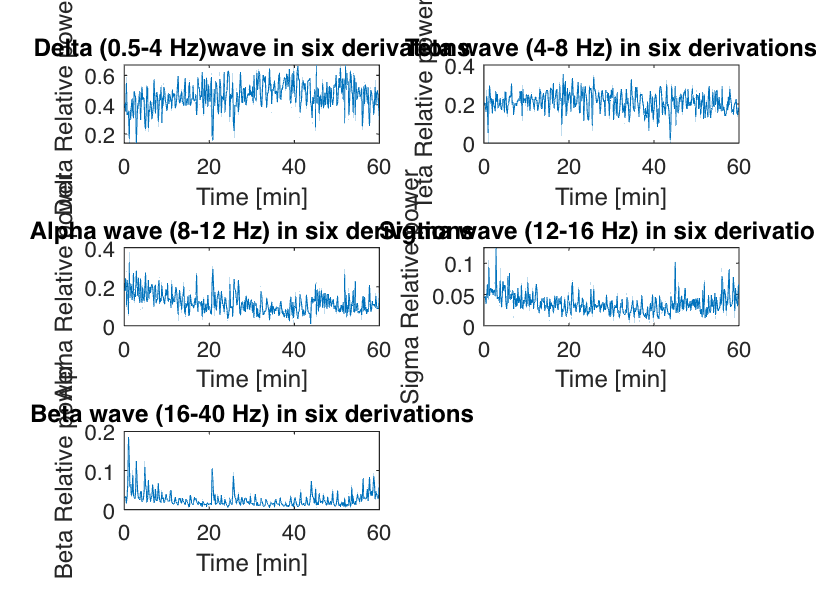


han=axes(fig,'visible','off'); 
han.Title.Visible='on';
mytitle='Relative power of eeg waves over time for 6 different derivations (colours)';
title(han,mytitle);

subplot 321
plot(t_min,mean(Pxx_mean_d))
title('Delta (0.5-4 Hz)wave in six derivations')
ylabel('Delta Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 322
plot(t_min,mean(Pxx_mean_t))
title('Teta wave (4-8 Hz) in six derivations')
ylabel('Teta Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 323
plot(t_min,mean(Pxx_mean_a))
title('Alpha wave (8-12 Hz) in six derivations')
ylabel('Alpha Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 324
plot(t_min,mean(Pxx_mean_s))
title('Sigma wave (12-16 Hz) in six derivations')
ylabel('Sigma Relative power')
xlabel ('Time [min]')
xlim([0 60])

subplot 325
plot(t_min,mean(Pxx_mean_b))
title('Beta wave (16-40 Hz) in six derivations')
ylabel('Beta Relative power')
xlabel ('Time [min]')
xlim([0 60]),clf

The mean values of each frequency band across all the leads can be computed, to show a "final" plot of relative power per frequency band across an hour. Also the stages and events of sleep should be displayed above this plot to compare the effect the stages and events into the energy plot.

## Analysis of the relationship between cardiac, respiratory, and brain parameters and the sleep and events stages

Vamos a hacer un calculo de la frecuencia cardiaca media, Hacer resampling de la frecuencia cardiaca para comparar (y hacer medias) entre las partes con apnea o sleep stages o no.

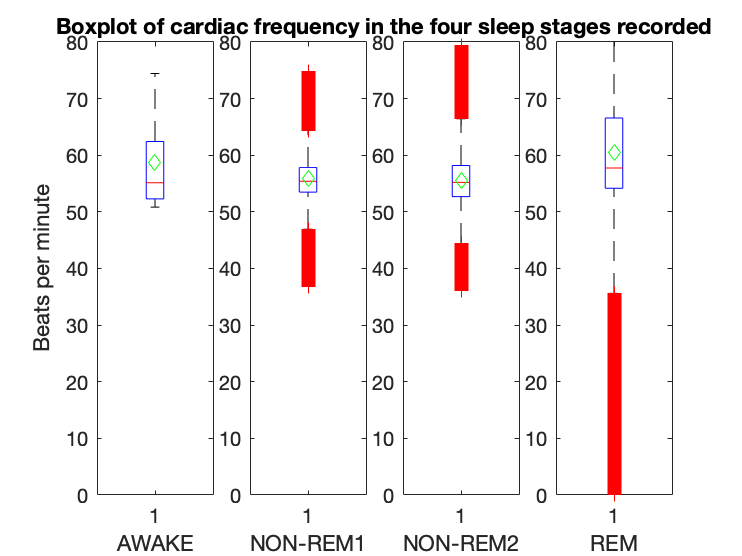

stage_names=data.sleepstages_names;
stage=data.sleepstages;

t = (n_epoch_start:n_epoch_end)/fs;
stages = stage(1:5,(n_epoch_start+1):n_epoch_end);
fcard_latmin_dr=resample(fcard_latmin_d, length(stages(1,:)),length(fcard_latmin_d));

title='Boxplot of cardiac frequency in the four sleep stages recorded';
y_label='Beats per minute'; 
y_lim=([0 80]);
signal=fcard_latmin_dr;

myboxplot(stages,signal,title,y_lim,y_label)

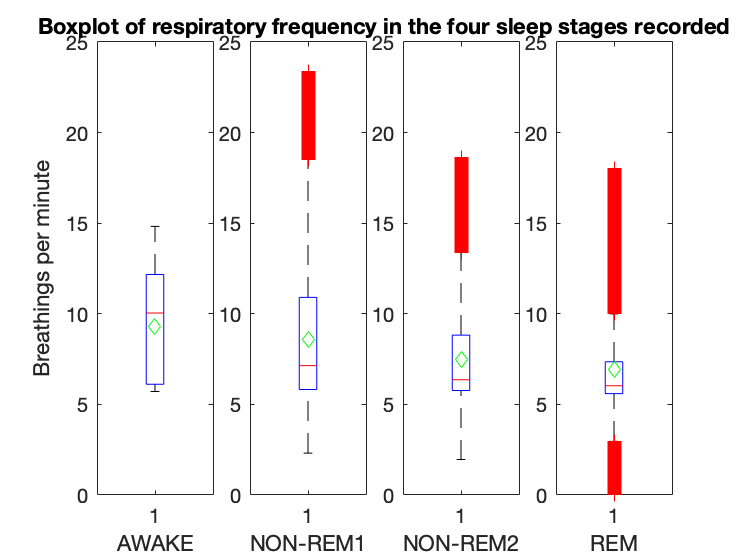

fresp_latmin_r=resample(fresp_latmin, length(stages(1,:)),length(fresp_latmin));

mytitle='Boxplot of respiratory frequency in the four sleep stages recorded';
y_lim=([0 25]);
y_label = 'Breathings per minute';
myboxplot(stages,fresp_latmin_r,mytitle,y_lim,y_label)

EEG waves relative energy during sleep stages

mean_dwave=resample(mean(Pxx_mean_d), length(stages(1,:)),length(mean(Pxx_mean_d)));
title='Boxplot of relative energy of delta wave in the four sleep stages recorded';
y_lim=([0 0.75]);
y_label='[V^2]'

y_label = '[V^2]'

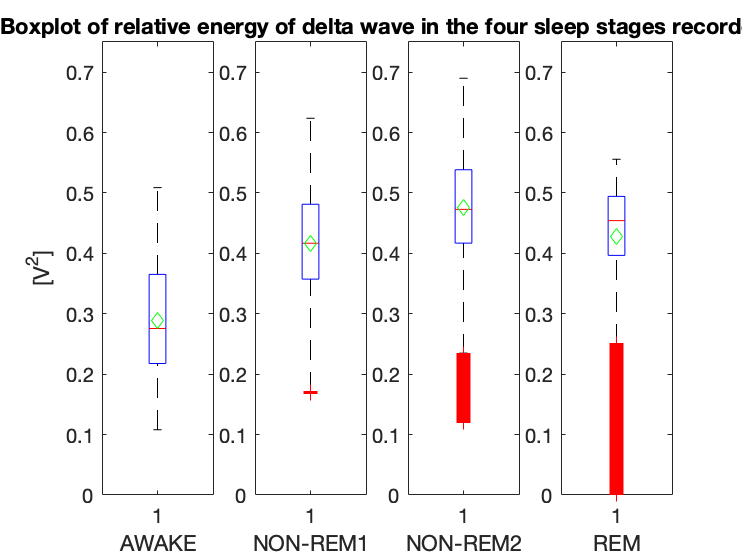

myboxplot(stages,mean_dwave,title,y_lim,y_label)

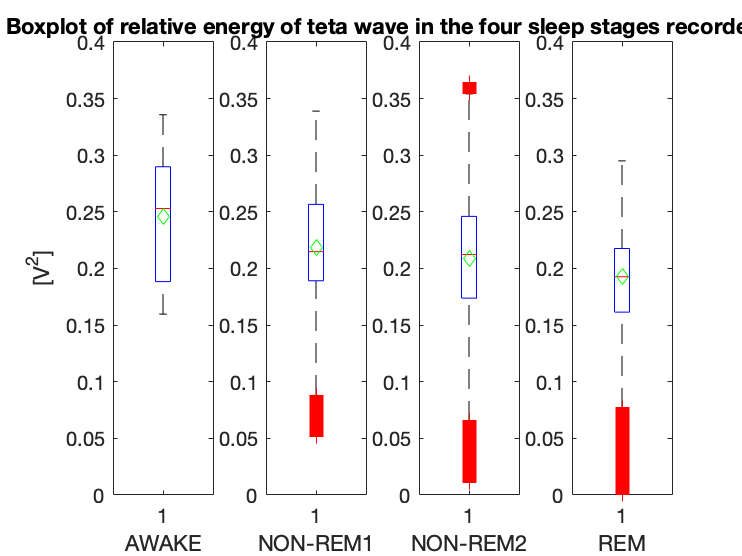

mean_dwave=resample(mean(Pxx_mean_t), length(stages(1,:)),length(mean(Pxx_mean_t)));
title='Boxplot of relative energy of teta wave in the four sleep stages recorded';
y_lim=([0 0.4]);
myboxplot(stages,mean_dwave,title,y_lim,y_label)

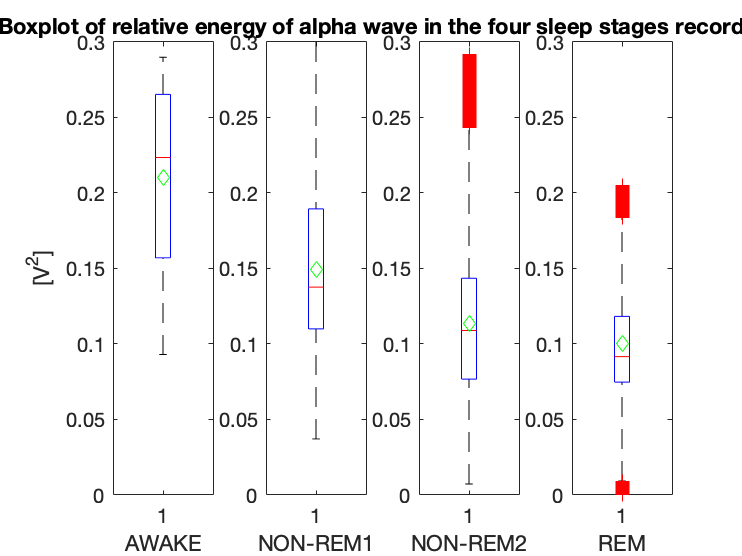


mean_dwave=resample(mean(Pxx_mean_a), length(stages(1,:)),length(mean(Pxx_mean_a)));
title='Boxplot of relative energy of alpha wave in the four sleep stages recorded';
y_lim=([0 0.3]);
myboxplot(stages,mean_dwave,title,y_lim,y_label)

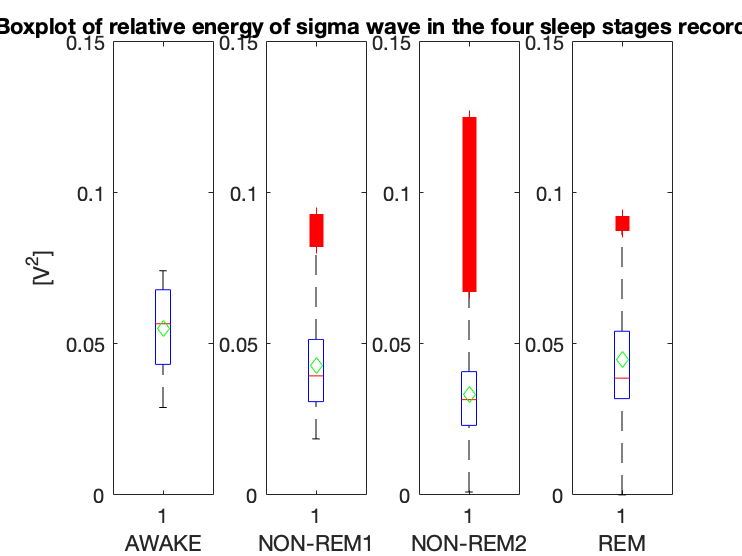


mean_dwave=resample(mean(Pxx_mean_s), length(stages(1,:)),length(mean(Pxx_mean_s)));
title='Boxplot of relative energy of sigma wave in the four sleep stages recorded';
y_lim=([0 0.15]);
myboxplot(stages,mean_dwave,title,y_lim,y_label)

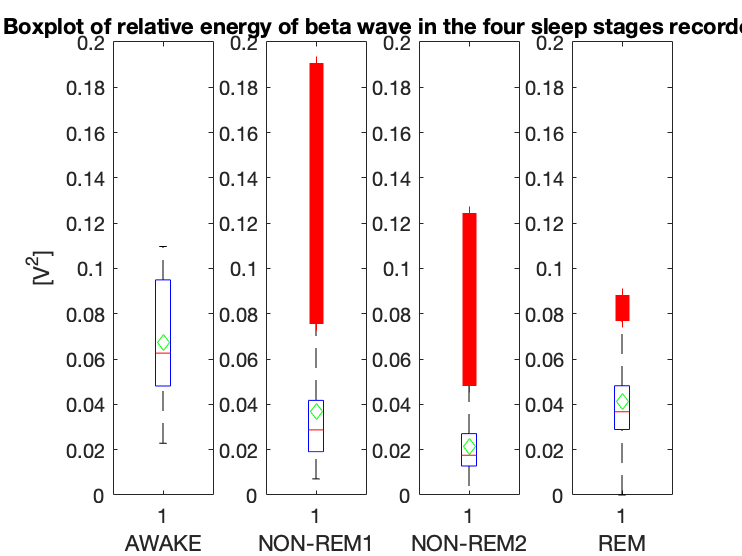

mean_dwave=resample(mean(Pxx_mean_b), length(stages(1,:)),length(mean(Pxx_mean_b)));
mytitle='Boxplot of relative energy of beta wave in the four sleep stages recorded';
y_lim=([0 0.2]);
myboxplot(stages,mean_dwave,mytitle,y_lim,y_label)

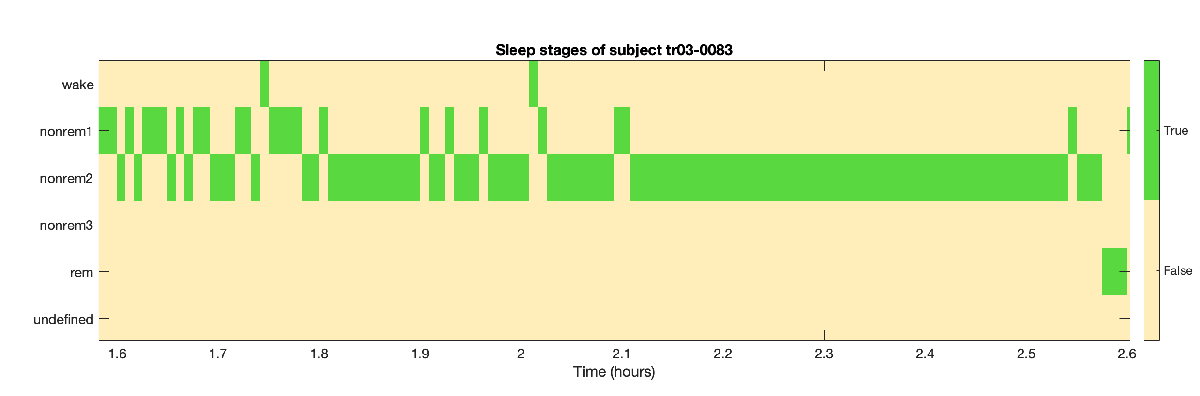

Functions:

function myspectogram(RRsim,fs,t,D,S, umbral, penval, Nridges, fdetection, reassign)

NFFT=2^max([10 nextpow2(D)]);
window=hamming(D);

if umbral ~= 0 && reassign ==1 %Both cases are met
[STFT,f,tSTFT,SPEC]=spectrogram (RRsim,window,S,NFFT,fs,'reassigned','MinThreshold',umbral);

elseif umbral ~= 0 && reassign ==0 %Only umbral
[STFT,f,tSTFT,SPEC]=spectrogram (RRsim,window,S,NFFT,fs,'MinThreshold',umbral);

elseif umbral == 0 && reassign ==1 %Only threshold
[STFT,f,tSTFT,SPEC]=spectrogram (RRsim,window,S,NFFT,fs,'reassigned');

elseif umbral == 0 && reassign ==0 %none
[STFT,f,tSTFT,SPEC]=spectrogram (RRsim,window,S,NFFT,fs);
end

Nplots=2;

figure()
subplot(Nplots,1,1)
plot(t,RRsim)
xlabel('t[s]'),ylabel('RR[s]'),title('RR simulated signal')
subplot(Nplots,1,2)
imagesc(tSTFT,f,SPEC) %Genera una images escalada entre 0 i e maximo de el SPEC
xlabel('t[s]'),ylabel('f[Hz]')
title(['Spectrogram of RRsim(t) with a ' num2str(D) ' samples Hamming window [V^2/Hz]'])
set(gca,'YDir','normal')
set(gca,'XLim',[t(1) t(end)])
YL=[0 0.5];
set(gca,'YLim',YL)

deltaf=diff(f(1:2));
nfb = ceil(fdetection/deltaf);%distance around which no adjacent ridge will be detected

[fridge,iridge,lridge] = tfridge(SPEC,f,penval,'NumRidges',Nridges,'NumFrequencyBins', nfb); % Calcula de un mapa tiempo frecuencia los valores con mayor potencia (las crestas)

figure()
imagesc(tSTFT,f,SPEC)
set(gca,'YDir','normal')
set(gca,'XLim',[t(1) t(end)])
YL=[0 0.5];
set(gca,'YLim',YL)
hold on
plot(tSTFT,fridge,'w')
xlabel('t[s]'),ylabel('f[Hz]')
title('Frequency of  the main ridge')
set(gca,'YLim',YL)
hold off
end

function myboxplot(stages,signal,mytitle,y_lim,y_label)
s=stages(1,1:length(signal));
s2=stages(2,1:length(signal));
s3=stages(3,1:length(signal));
s5=stages(5,1:length(signal));

sign=zeros(720000,4);
sign(:,1)=(s.*signal);
sign(:,2)=(s2.*signal);
sign(:,3)=(s3.*signal);
sign(:,4)=(s5.*signal);

fig=figure;clf


sign1=sign(:,1);
sign2=sign(:,2);
sign3=sign(:,3);
sign5=sign(:,4);


subplot 141
boxplot(sign1(sign1~=0))
ylim(y_lim);
xlabel('AWAKE')
hold on
plot(mean(sign1(sign1~=0)),'dg')
hold off

subplot 142
boxplot(sign2(sign2~=0))
ylim(y_lim);
xlabel('NON-REM1')
hold on
plot(mean(sign2(sign2~=0)),'dg')
hold off

subplot 143
boxplot(sign3(sign3~=0))
ylim(y_lim);
xlabel('NON-REM2')
hold on
plot(mean(sign3(sign3~=0)),'dg')
hold off

subplot 144
boxplot(sign5(sign5~=0))
ylim(y_lim);
xlabel('REM')
hold on
plot(mean(sign5(sign5~=0)),'dg')
hold off


% Give common xlabel, ylabel and title to your figure
han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.YLabel.Visible='on';
ylabel(han,y_label);
title(han,mytitle);

end